# Solutions to the bistable equation linearized about a front solution 

The bistable equation is a PDE given via 


$$u_t = u_{xx} + 2u\left(u - \frac{1}{2} \right)(1-u).$$


If we are interested in steady state solutions, we can form the ODE $u_{xx} + 2u\left(u - \frac{1}{2} \right)(1-u) = 0$. Forming the first order system, we obtain 

$\pmatrix{\dot u \cr \dot v} = \pmatrix{v \cr -u(2u-1(1-u)} := f(u,v)$.

This system has saddle fixed points $(0,0), (1,0)$ and center fixed point $(1/2,0)$. There are two heteroclinic orbits connecting the saddles given by 

$\varphi_0 = \frac{1}{1 + e^{-x}}$ and $\varphi_1 = \frac{1}{1+e^x}$. 

### Unstable Manifold

If our fixed point is the origin, then the unstable manifold at the origin is given by 

$\gamma(x) = \big(\varphi_0(x), \varphi_0'(x) \big) = \left(\frac{1}{1+e^{-x}}, \frac{e^{-x}}{(1+e^{-x})^2} \right)$. 

We can plot this unstable manifold in phase space by using the analytic expression given above and by using the parameterization method. 

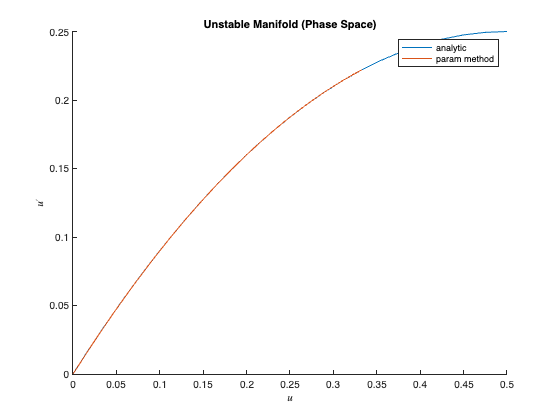

params.b = 2;
params.bundle.order = 20;
params.mfld.order = 20;
params.mfld.scale = 1/2; 
params.bundle.scale = 1/2; 
params = jacobian_eigenpairs(params);
params.fp = [0;0];

params.sigma_0 = 1; 

x_range = -10:.1:0;
[mfld_a1, mfld_a2] = mfld_coords_an(x_range); 
mfld_pm = mfld_coords_pm(params);

figure 
hold on 
plot(mfld_a1, mfld_a2)
plot(mfld_pm(:,1), mfld_pm(:,2))
legend('analytic', 'param method')
title('Unstable Manifold (Phase Space)')
xlabel('$u$', Interpreter = 'latex')
ylabel('$u^\prime$', Interpreter = 'latex')

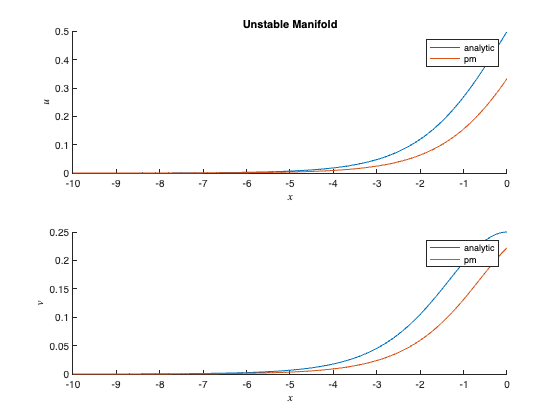

params.mfld.coeffs = mfld_coeff(params, 'unstable'); 
[mfld_pm1, mfld_pm2] = mfld_coords_x(params, x_range);

figure
tiledlayout(2,1)
nexttile 
title('Unstable Manifold')
hold on
plot(x_range, mfld_a1)
plot(x_range, mfld_pm1)
legend('analytic', 'pm')
xlabel('$x$', Interpreter = 'latex')
ylabel('$u$', Interpreter = 'latex')
nexttile 
hold on
plot(x_range, mfld_a2)
plot(x_range, mfld_pm2)
legend('analytic', 'pm')
xlabel('$x$', Interpreter = 'latex')
ylabel('$v$', Interpreter = 'latex')

We can see that the unstable manifold computed analytically and via the parameterization method appear to be shifted in the independent variable. Recall $\gamma(t)$ be the unstable manifold computed analytically and $\gamma_{pm}(t; \sigma_0) = Q(e^t\sigma_0) = \sum_{k = 0}^\infty q_k (e^t\sigma_0)^k$. We seek $\sigma_0$ and appropriate initial conditions so that these solutions coincide on the same time scale. 

We fix $t = -1$ and plot the function $f(\sigma_0) = \gamma_{pm}(0,\sigma_0) - \gamma(-1)$ and look for the zeros. 

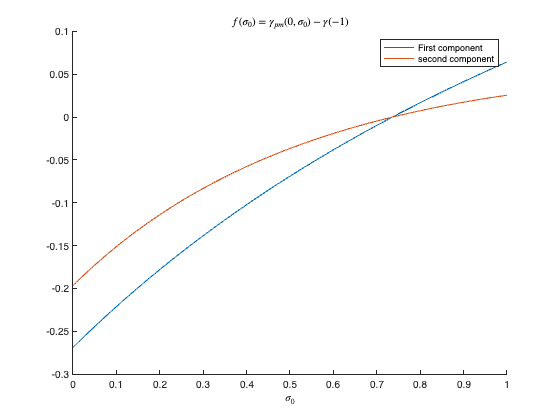

t = -1;

[u_1, u_2] = mfld_coords_an([t]);
x = 0:.005:1; 
sig1 =  params.mfld.coeffs(:,1)'*((x)'.^[0:1:params.mfld.order])' - u_1; 
sig2 = params.mfld.coeffs(:,2)'*((x)'.^[0:1:params.bundle.order])' - u_2; 

figure 
hold on 
plot(x, sig1)
plot(x, sig2)
legend('First component', 'second component')
xlabel('$\sigma_0$', Interpreter = 'latex')
title('$f(\sigma_0) = \gamma_{pm}(0,\sigma_0) - \gamma(-1)$', Interpreter = 'latex')

We find that $\gamma_{pm}(0;\sigma_0) = \gamma(-1)$ for  $\sigma_0 \approx .73$. Therefore, we set $\tilde\gamma(t) = \gamma(t-1)$ and plot $\tilde \gamma(t)$ and $\gamma_{pm}(t)$ for $t \in [-10,0]$. We find that the two unstable manifolds correspond on this time scale. 

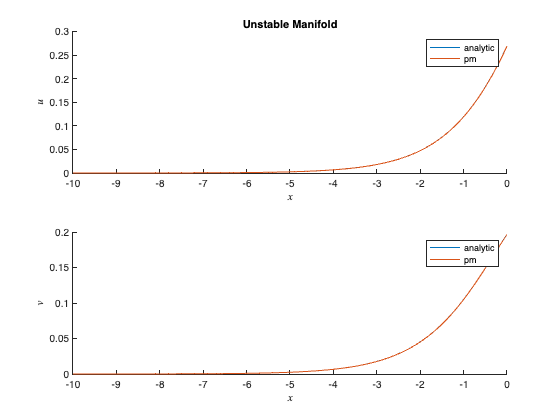

zero_index = find(diff(sign(sig1 - sig2))); 
params.sigma_0 = x(zero_index); 
shift = 1;

x_range = -10:.1:0;
[mfld_a1, mfld_a2] = mfld_coords_an(x_range-shift); 
[mfld_pm1, mfld_pm2] = mfld_coords_x(params, x_range);

figure
tiledlayout(2,1)
nexttile 
title('Unstable Manifold')
hold on
plot(x_range, mfld_a1)
plot(x_range, mfld_pm1)
legend('analytic', 'pm')
xlabel('$x$', Interpreter = 'latex')
ylabel('$u$', Interpreter = 'latex')
nexttile 
hold on
plot(x_range, mfld_a2)
plot(x_range, mfld_pm2)
legend('analytic', 'pm')
xlabel('$x$', Interpreter = 'latex')
ylabel('$v$', Interpreter = 'latex')

### Unstable Solution to the Variational Equation

The solution $\varphi = \frac{1}{1+e^{-x}}$ is a steady state front solution. Linearizing about this solution, we obtain the ODE $y_{xx} + [-6\varphi^2(x) + 6 \varphi(x) -1]y = 0$. We form the first order system: 


$$\pmatrix{\dot u \cr \dot v} = \pmatrix{v \cr [6\varphi^2 - 6\varphi + 1]u} = \pmatrix{0 & 1 \cr 1 & 0} \pmatrix{u \cr v} - \pmatrix{0 \cr \frac{3}{2}\sech^2\left(\frac{x}{2} \right)u}. $$


We can understand the unstable vector bundle to the unstable manifold as both the derivative of the unstable manifold (in the above plot) and as the solution to the variational equation. We compute this solution to the variational equation using the parameterization method and by differentiating the front.  

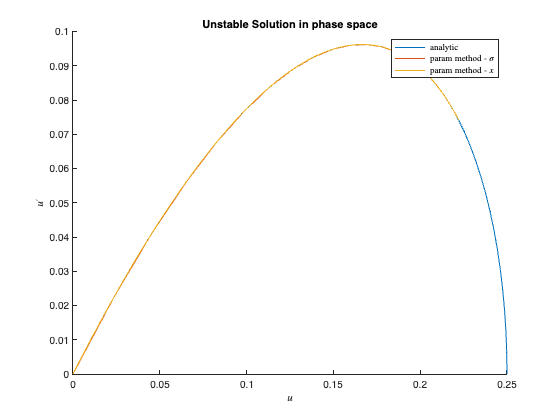

ub_coeffs = ub_coeff(params);
delta = .05; 
x_range = -10:delta:0;
params.sigma_0 = 1; 

[us_a1, us_a2] = ub_coords_an(x_range);
ub_coords = ub_coords_pm(params);
[us_pm1, us_pm2] = ub_coords_x(params, ub_coeffs, x_range);


figure 
hold on 
plot(us_a1, us_a2)
plot(ub_coords(:,1), ub_coords(:, 2))
plot(us_pm1, us_pm2)
xlabel('$u$', Interpreter = 'latex')
ylabel('$u^\prime$', Interpreter = 'latex')

legend('analytic', 'param method - $\sigma$', 'param method - $x$', Interpreter = 'latex')
title('Unstable Solution in phase space')

We compute the parameterization as $v(\sigma) = \sum_{k = 0} v_k \sigma^k$ for $\sigma \in [0,1]$ and then plot the solution $U_{pm}^u(t; \sigma_0) = \sigma_0e^t  v^u\big(e^t\sigma_0\big)$. Additionally, we compute the unstable solution using the analytic expression from matlab, $U^u_a(t)$ for $x \in [-10, 0]$. To begin with, we set $\sigma_0 = 1$. 

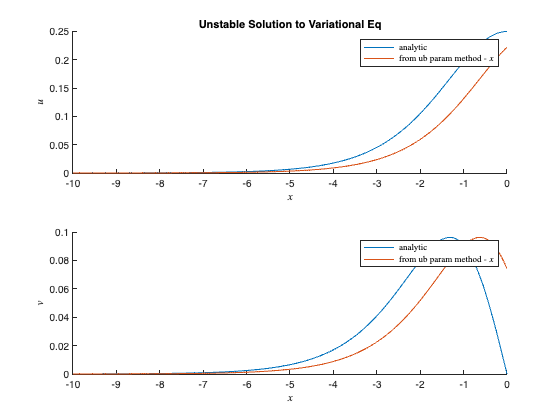

figure 
tiledlayout(2,1)
nexttile
hold on 
plot(x_range, us_a1)
plot(x_range, us_pm1)
legend('analytic', 'from ub param method - $x$', Interpreter = 'latex')
title('Unstable Solution to Variational Eq')
xlabel('$x$', Interpreter = 'latex')
ylabel('$u$', Interpreter = 'latex')
nexttile 
hold on 
plot(x_range, us_a2)
plot(x_range, us_pm2)
legend('analytic', 'from ub param method - $x$', Interpreter = 'latex')
xlabel('$x$', Interpreter = 'latex')
ylabel('$v$', Interpreter = 'latex')

It appears that these solutions have been shifted in the independent variable. Before trying to compute $\sigma_0$, we first verify that both of these solutions solve the variational equation. It is important to note that $U^u(t;\sigma)$ will not necessarily solve the variational equation as written above due to this shift in time scale. Instead we verify that 

$\dot U^u(t;\sigma_0) = Df\circ Q(t; \sigma_0)U^u(t; \sigma_0)$.

First we check that the analytic expression for the unstable solution solves the variational equation. These should agree because we derived the solution analytically in Mathematica. 

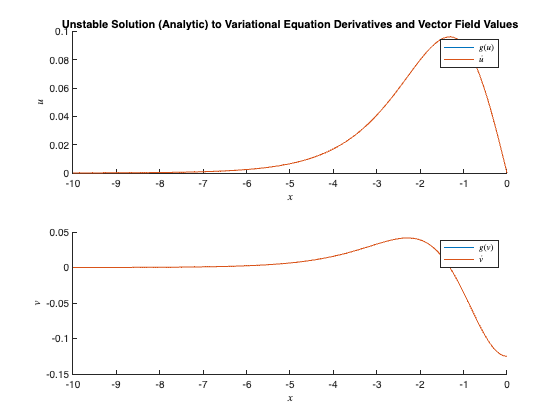

vals = bistable_variational_eq(params, x_range, [us_a1; us_a2]);

diff_d1 = us_a2;
diff_d2 = (exp(x_range).*(1 - 4.*exp(x_range) + exp(2.*x_range)))./(1 + exp(x_range)).^4;

diff_vals = [diff_d1; diff_d2];

figure 
tiledlayout(2,1)
nexttile 
hold on
plot(x_range, vals(1,:))
plot(x_range, diff_vals(1,:))
legend('$g(u)$', '$\dot u$', Interpreter = 'latex')
title('Unstable Solution (Analytic) to Variational Equation Derivatives and Vector Field Values')
xlabel('$x$', Interpreter = 'latex')
ylabel('$u$', Interpreter = 'latex')
nexttile 
hold on
plot(x_range, vals(2,:))
plot(x_range, diff_vals(2,:))
legend('$g(v)$', '$\dot v$', Interpreter = 'latex')
xlabel('$x$', Interpreter = 'latex')
ylabel('$v$', Interpreter = 'latex')

Now we check that the solution derived from the parameterization method solves the ODE. The first component agrees but the second does not. 

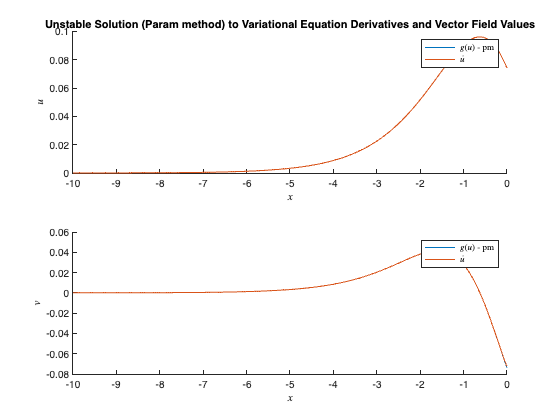

mfld_coeffs = mfld_coeff(params, 'unstable');
vals = bistable_variational_eq(params, x_range, [us_pm1; us_pm2]);

vals_pm = bistable_variational_eq_pm(params, x_range, [us_pm1; us_pm2]);

[diff1, diff2] = ub_deriv_coords_x(params, ub_coeffs, x_range);

figure 
tiledlayout(2,1)
nexttile 
title('Unstable Solution (Param method) to Variational Equation Derivatives and Vector Field Values')
hold on
plot(x_range, vals_pm(1,:))
plot(x_range, diff1)
xlabel('$x$', Interpreter = 'latex')
ylabel('$u$', Interpreter = 'latex')
legend('$g(u)$ - pm', '$\dot u$', Interpreter = 'latex')
nexttile 
hold on
plot(x_range, vals_pm(2,:))
plot(x_range, diff2)
xlabel('$x$', Interpreter = 'latex')
ylabel('$v$', Interpreter = 'latex')
legend('$g(u)$ - pm', '$\dot u$', Interpreter = 'latex')

Now we try to find the appropriate $\sigma_0$ so that $U^u_{pm}(t; \sigma)$ and $U^u_a(t)$ agree on the same time axis. 

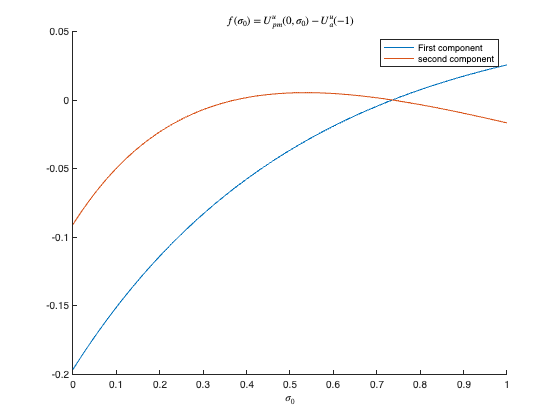

t = -1;

[u_1, u_2] = ub_coords_an([t]);
x = 0:.005:1; 
sig1 =  ub_coeffs(1,:)*x'.^[1:1:params.bundle.order+1]' - u_1; 
sig2 = ub_coeffs(2,:)*x'.^[1:1:params.bundle.order+1]' - u_2; 

figure 
hold on 
plot(x, sig1)
plot(x, sig2)
legend('First component', 'second component')
title('$f(\sigma_0) = U^u_{pm}(0,\sigma_0) - U^u_a(-1)$', Interpreter = 'latex')
xlabel('$\sigma_0$', Interpreter = 'latex')

For $t = -1$, we have that $\sigma_0 \approx .7350$. Note that this is the same $\sigma_0$ and shift in $t$ that brings the two formulations of the unstable manifold into alignment on the same time axis. 

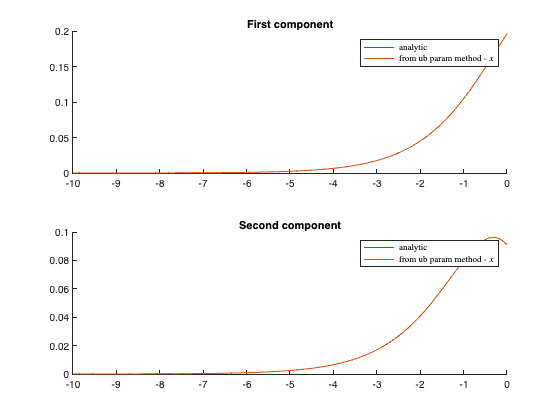

zero_index = find(diff(sign(sig1 - sig2))); 
params.sigma_0 = x(zero_index); 
shift = 1;

[us_a1, us_a2] = ub_coords_an(x_range - shift);
[us_pm1, us_pm2] = ub_coords_x(params, ub_coeffs, x_range);

figure 
tiledlayout(2,1)
nexttile
hold on 
plot(x_range, us_a1)
plot(x_range, us_pm1)
legend('analytic', 'from ub param method - $x$', Interpreter = 'latex')
title('First component')
nexttile 
hold on 
plot(x_range, us_a2)
plot(x_range, us_pm2)
legend('analytic', 'from ub param method - $x$', Interpreter = 'latex')
title('Second component')

### Stable Solution

Now we seek the solution to the variational equation that has growth rate $e^{-x}$. We have an analytic expression for this solution and we seek to find it using the reduction of order method. The solution from the reduction of order method is given via $U^s_{roo}(t; \sigma_0) = w(t; \sigma_0)U^u(t; \sigma_0)$ where 


$$w'(t; \sigma_0) = \sum_{k = -2}^\infty w_k\left( \sigma_0 e^t \right)^k$$


and is derived via power matching. 

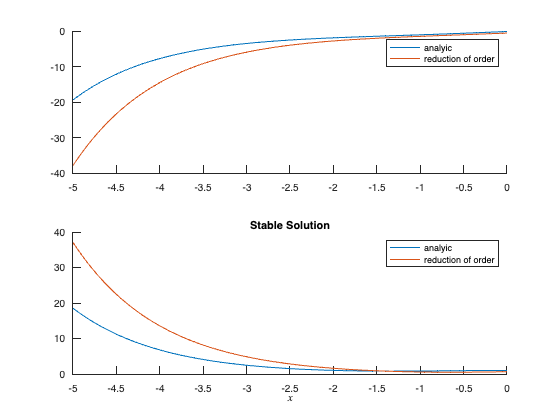

x_range = -5:delta:0;

params.sigma_0 = 1; 
shift = 0; 

[sb1_a, sb2_a] = sb_coords_an(x_range - shift);
v_coeff = sb_product_deriv_coeff(ub_coeffs, params);

ss_coords = sb_coords_roo(x_range, params, v_coeff, ub_coeffs);

figure 
tiledlayout(2,1)
nexttile
hold on 
plot(x_range, sb1_a)
plot(x_range, ss_coords(1,:))
legend('analyic', 'reduction of order')
nexttile 
hold on
plot(x_range, sb2_a)
plot(x_range, ss_coords(2,:))
legend('analyic', 'reduction of order')
xlabel('$x$', Interpreter = 'latex')
title('Stable Solution')

We verify the analytic solution solves the ODE as a sanity check. 

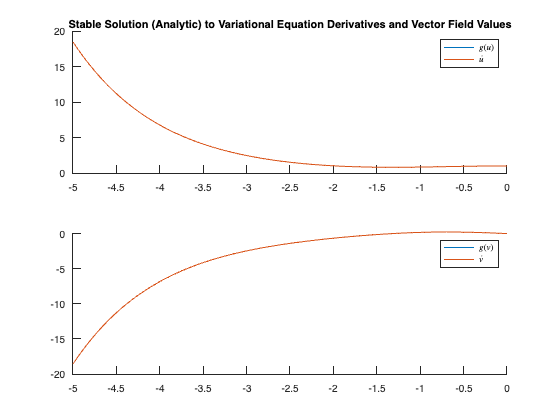

vals = bistable_variational_eq(params, x_range, [sb1_a; sb2_a]);

diff_d1 = sb2_a;
diff_d2 = (exp(-x_range).*(12.*exp(2.*x_range) - 12.*exp(3.*x_range) + 12.*exp(4.*x_range) + 5.*exp(5.*x_range) + 3.*exp(x_range) + 8.*exp(2.*x_range).*(3.*x_range + 7) - 12.*exp(3.*x_range).*(3.*x_range - 7)))./(8.*(exp(x_range) + 1).^3) - (exp(-x_range).*(3.*exp(4.*x_range) + exp(5.*x_range) + 3.*exp(x_range) + 4.*exp(2.*x_range).*(3.*x_range + 7) - 4.*exp(3.*x_range).*(3.*x_range - 7) + 1))./(8.*(exp(x_range) + 1).^3) - (3.*(3.*exp(4.*x_range) + exp(5.*x_range) + 3.*exp(x_range) + 4.*exp(2.*x_range).*(3.*x_range + 7) - 4.*exp(3.*x_range).*(3.*x_range - 7) + 1))./(8.*(exp(x_range) + 1).^4);

figure 
tiledlayout(2,1)
nexttile 
hold on
plot(x_range, vals(1,:))
plot(x_range, diff_d1)
legend('$g(u)$', '$\dot u$', Interpreter = 'latex')
title('Stable Solution (Analytic) to Variational Equation Derivatives and Vector Field Values')
nexttile 
hold on
plot(x_range, vals(2,:))
plot(x_range, diff_d2)
legend('$g(v)$', '$\dot v$', Interpreter = 'latex')

We keep the same $\sigma_0$ and time shift as with the unstable bundle and the unstable manifold and plot $U^s_{roo}(t; \sigma_0)$ and $\tilde U^s_a(t) := U^s_a(t-1)$. We see that for $\sigma_0 \approx .735$, these two solutions coincide on the same domain, $t \in [-5,0]$. 

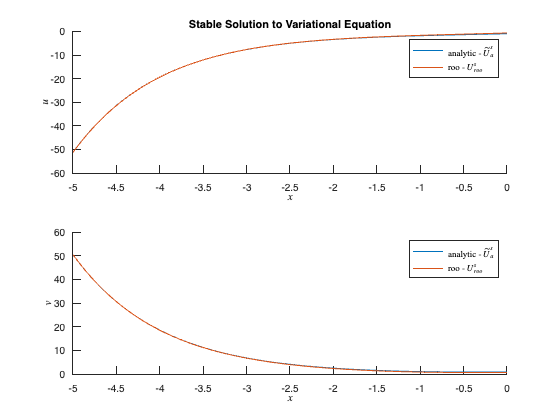

params.sigma_0 = .735;
shift = 1;

[ss_a1, ss_a2] = sb_coords_an(x_range - shift);
ss_coords = sb_coords_roo(x_range, params, v_coeff, ub_coeffs);

figure 
tiledlayout(2,1)
nexttile
hold on 
plot(x_range, ss_a1)
plot(x_range, ss_coords(1,:))
legend('analytic - $\tilde U^s_a$', 'roo - $U^s_{roo}$', Interpreter = 'latex')
title('Stable Solution to Variational Equation')
xlabel('$x$', Interpreter = 'latex')
ylabel('$u$', Interpreter = 'latex')
nexttile 
hold on 
plot(x_range, ss_a2)
plot(x_range, ss_coords(2,:))
legend('analytic - $\tilde U^s_a$', 'roo - $U^s_{roo}$', Interpreter = 'latex')
xlabel('$x$', Interpreter = 'latex')
ylabel('$v$', Interpreter = 'latex')

We can also verify that the stable solution satisfies the variational equation $\dot u(t; \sigma_0) = Df \circ Q(t; \sigma_0) u(t; \sigma_0)$. 

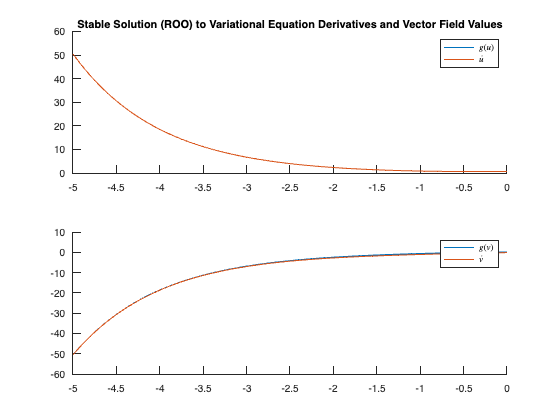

vals = bistable_variational_eq_pm(params, x_range, ss_coords);

deriv_coords = sb_deriv_coords_x_roo(x_range, params, v_coeff, ub_coeffs);

diff_d1 = deriv_coords(1,:);
diff_d2 = deriv_coords(2,:);

figure 
tiledlayout(2,1)
nexttile 
title('Stable Solution (ROO) to Variational Equation Derivatives and Vector Field Values')
hold on
plot(x_range, vals(1,:))
plot(x_range, diff_d1)
legend('$g(u)$', '$\dot u$', Interpreter = 'latex')
nexttile 
hold on
plot(x_range, vals(2,:))
plot(x_range, diff_d2)
legend('$g(v)$', '$\dot v$', Interpreter = 'latex')

### Parameterization Method Coefficient Check 

Here we check that the coefficients computed for the manifold and unstable bundle decay exponentially. 

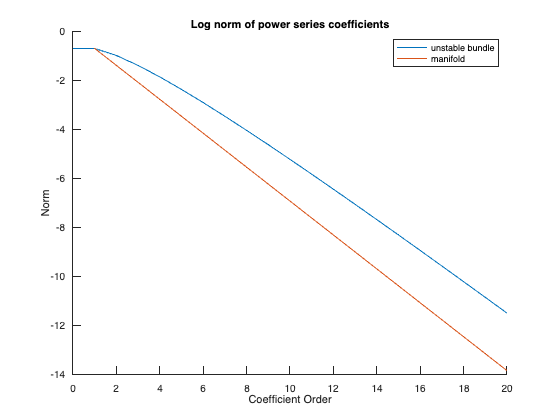

x = 0:1:max(size(mfld_coeffs))-1;

figure 
hold on 
plot(x, log(abs(ub_coeffs(1,:))))
plot(x, log(abs(mfld_coeffs(:,1))))
legend('unstable bundle', 'manifold')
title('Log norm of power series coefficients')
xlabel('Coefficient Order')
ylabel('Norm')